# **IO643 & IO644 - CANopen Loopback**

The IO643 and IO644 are CANopen modules to connect real-time target machines to industrial equipment. The IO643 is a CANopen Master module that is used to communicate with field level devices such as motor controllers and sensors. The IO644 is a CANopen Slave module that is used to communicate with devices on the control and process level such as programmable logic controllers. The modules handle the complete data exchange between the real-time application and the connected devices. The data exchange is processed via a dual-port memory. Each module acts as one CANopen station exclusively.

CANopen communication typically takes place between one CANopen Master and multiple CANopen Slaves. In this example, one master (IO643) communicates with one slave (IO644), installed in the same machine. The modules are configured to exchange some generic values.

The IO643 requires a configuration file (included with this example). The file is created with SYCON.net, a software tool from Hilscher.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO643 and one IO644 installed

- Terminated loopback CAN cable

The IO643 requires a configuration file. This file comes with the example model and does not have to be created. However, the SYCON.net project is also included in the example and can be used to recreate the configuration file. To introduce the IO644 module to SYCON.net, you must export the IO644 EDS (electronic data sheet) file from the IO644 Setup block and import it into SYCON.net. The module help documentation and the SYCON documentation explain how to use SYCON.net, which is free of charge. Find the download link in the Additional References section below.

### Test Setup

CANopen is a fieldbus protocol based on standard CAN. Use a cable as defined in the IO643 pin mapping documentation to connect the IO643 with the IO644.

## Initialize and Open the Simulink model

 
% Sample time
Ts = 0.001;

% Open Simulink model
modelName = 'sgMdl_IO643_IO644_CANopenLoopback';
open_system(modelName);

### Model Description

The model sets up the communication for both the IO643 and IO644. 

The basic CAN settings, device identity and monitoring options of the IO644 are set by the [IO644 Setup block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io644_setup_v2). The [IO644 Object blocks](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io644_object) are used to create a local object dictionary. Remote devices can read and write these objects via the PDO (process data object) and SDO (service data object) protocols. SDO access is enabled by default. PDOs are configured with the [IO644 PDO blocks](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io644_pdo). 

When starting the model, the [IO643 Setup block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io643_setup) loads the corresponding configuration file onto the I/O module. The [IO643 Receive](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io643_receive) and [Send blocks](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io643_send) exchange PDOs with the IO644. The [SDO Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io643_sdo_read) and [Write blocks](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io643_sdo_write) access the IO644 objects directly. 

The Object dictionary of the IO644 looks as follows:

- Object 0x4000 sub-index 0 is a stand-alone object holding a value of type int16. The corresponding signal is S2M_Constant. The IO643 overwrites this value using the SDO Write block.

- Object 0x4001 is a parent object containing 3 sub-objects.

- Object 0x4001 sub-index 1 is a sub-object holding a value of type uint32. The corresponding Object block cyclically updates this value. The object is mapped to TxPDO 1 which the IO644 sends to the IO643 only if the value changes (event-driven transmission). The IO643 Receive block outputs the signal. The signal name is S2M_Counter which matches the name of the corresponding object.

- Object 0x4001 sub-index 2 is a sub-object holding a value of type single. The corresponding Object block cyclically updates this value. The object is mapped to TxPDO 2 which the IO644 periodically sends to the IO643 (synchronous cyclic transmission). The IO643 Receive block outputs the signal. The signal name is S2M_Sine which matches the name of the corresponding object.

- Object 0x4001 sub-index 3 is a sub-object holding a value of type uint8. The corresponding Object block cyclically updates this value. The object is also mapped to TxPDO 2. The IO643 Receive block outputs the signal. The signal name is S2M_Pulse which matches the name of the corresponding object.

- Object 0x6000 sub-index 0 is a stand-alone object holding a value of type int8. The corresponding signal is M2S_Constant. The IO643 reads this value using the SDO Read block.

- Object 0x6001 is a parent object containing 3 sub-objects.

- Object 0x6001 sub-index 2 is a sub-object holding a value of type double. The object is mapped to RxPDO 1 which the IO643 periodically sends to the IO644 (synchronous cyclic transmission). The corresponding Object block outputs this value. The signal name is S2M_Sine which matches the name of the object.

- Object 0x6001 sub-index 1 is a sub-object holding a value of type uint16. The object is mapped to RxPDO 2 which the IO643 sends to the IO644 only if the value changes (event-driven transmission). The corresponding Object block outputs this value. The signal name is S2M_Counter which matches the name of the object.

- Object 0x6001 sub-index 3 is a sub-object holding a value of type int32. The object is mapped to RxPDO 2 which the IO643 sends to the IO644 only if the value changes (event-driven transmission). The corresponding Object block outputs this value. The signal name is S2M_Pulse which matches the name of the object.

4 PDOS are defined. RxPDO 1 and RxPDO 2 are sent from the IO643 to the IO644. TxPDO 1 and TxPDO 2 are sent from the IO644 to the IO643. According to the data types of the mapped objects, the PDOs have the following lengths:

- RxPDO 1: 8 bytes (double)

- RxPDO 2: 6 bytes (uint16 + int32)

- TxPDO 1: 4 bytes (uint32)

- TxPDO 2: 5 bytes (single + uint8)

Only RxPDO 1 completes the maximum PDO length of 8 bytes. The other PDOs could ingest additional object data (additional objects to be mapped).

The overall data length for the IO643-to-IO644 direction is 8+6=14 bytes, which equals the **Number of Bytes** parameter of the IO643 Send block. The overall data length for the IO644-to-IO643 direction is 4+5=9 bytes, which equals the **Number of Bytes** parameter of the IO643 Receive block. In the IO643 input and output process data images, the PDO data is packed in a row without padding bytes.

The model illustrates how to use [Byte Packing](https://www.mathworks.com/help/slrealtime/io_ref/bytepacking.html) blocks to pack the signals into one byte array to be processed by the Send block. [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) blocks are used to extract the signals from the byte array that the Receive block outputs. Use the function described [here](https://www.speedgoat.com/help/slrt/page/io_main/refentry_sgapi_model_create_from_sycon) to automatically generate the signal packing and unpacking from a SYCON.net configuration file.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Wait until connection is established
pause(5);

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(2,2);
Simulink.sdi.view;

% Start the real-time application
tg.start;

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('S2M_Counter');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('S2M_Pulse');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('S2M_Sine');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('S2M_Constant');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('M2S_Counter');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('M2S_Pulse');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('M2S_Sine');
plotOnSubPlot(s,2,2,true);
s = sdiLatestRun.getSignalsByName('M2S_Constant');
plotOnSubPlot(s,2,2,true);

Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,10,-10,110]);
Simulink.sdi.setSubplotLimits(1,2,'AllRange',[0,10,-110,110]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,10,-10,110]);
Simulink.sdi.setSubplotLimits(2,2,'AllRange',[0,10,-110,110]);


### Check the Results

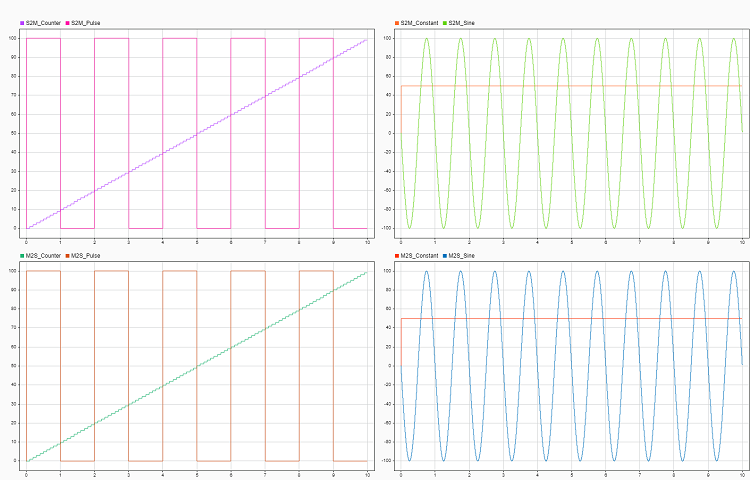

## Additional References

- [IO643 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io643)

- [IO644 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io644)